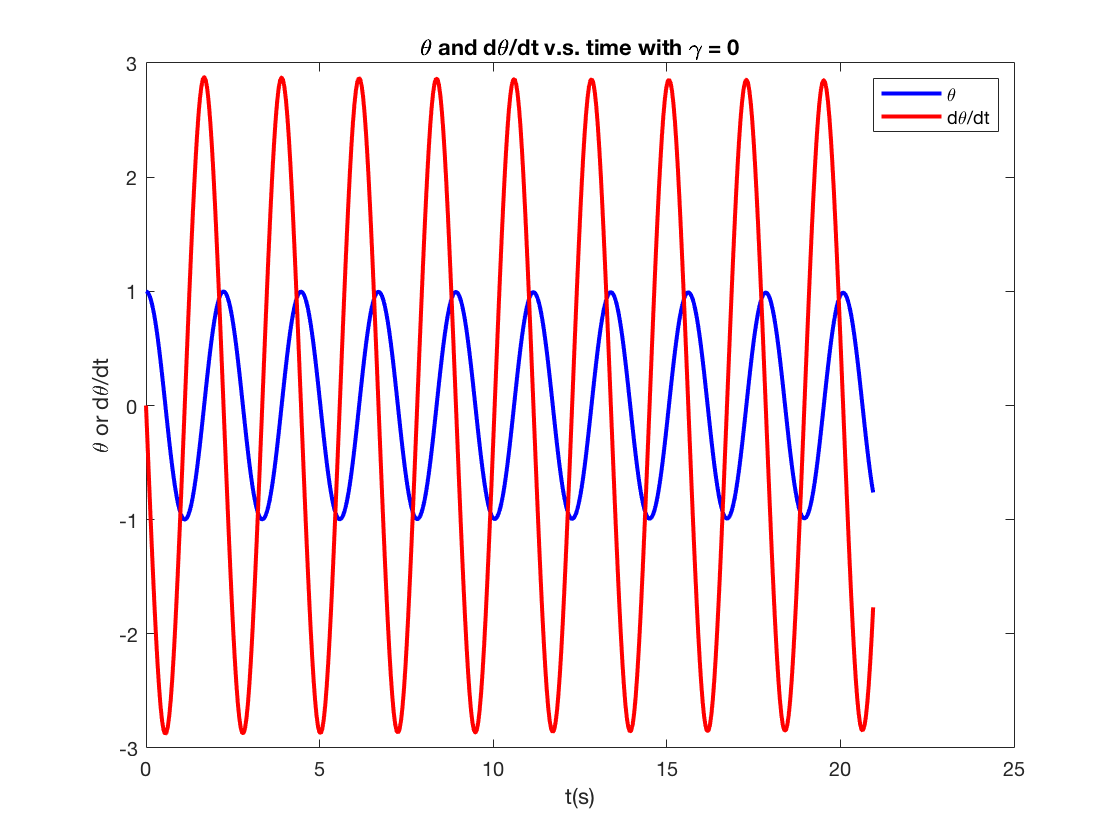


[T, sol] = damped_oscillator(3,0,1,0);

T_undamped = T;
omega_undamped = 2*pi/T_undamped;
disp(['Undamped period is ' num2str(T_undamped),', freq is ',num2str(omega_undamped)])

Undamped period is 2.2046, freq is 2.85


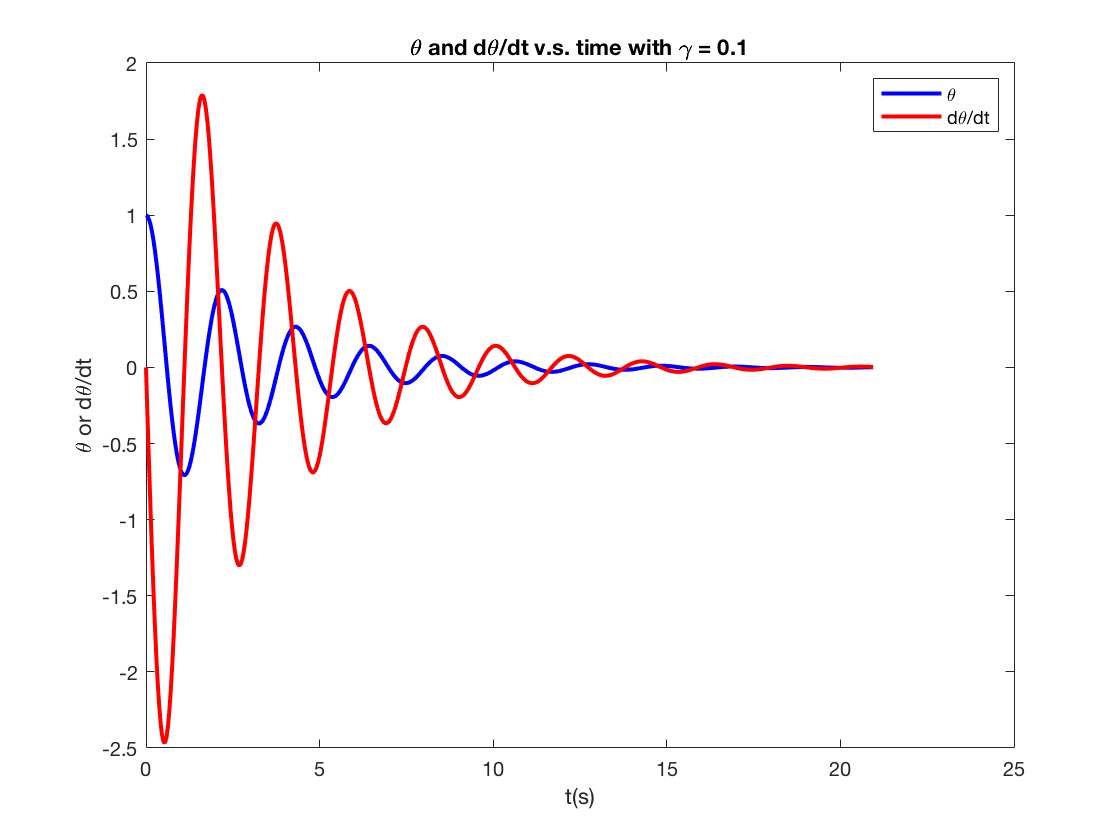

T = 2.1166

T ratio = 0.9601, ang. freq. ratio is 1.042


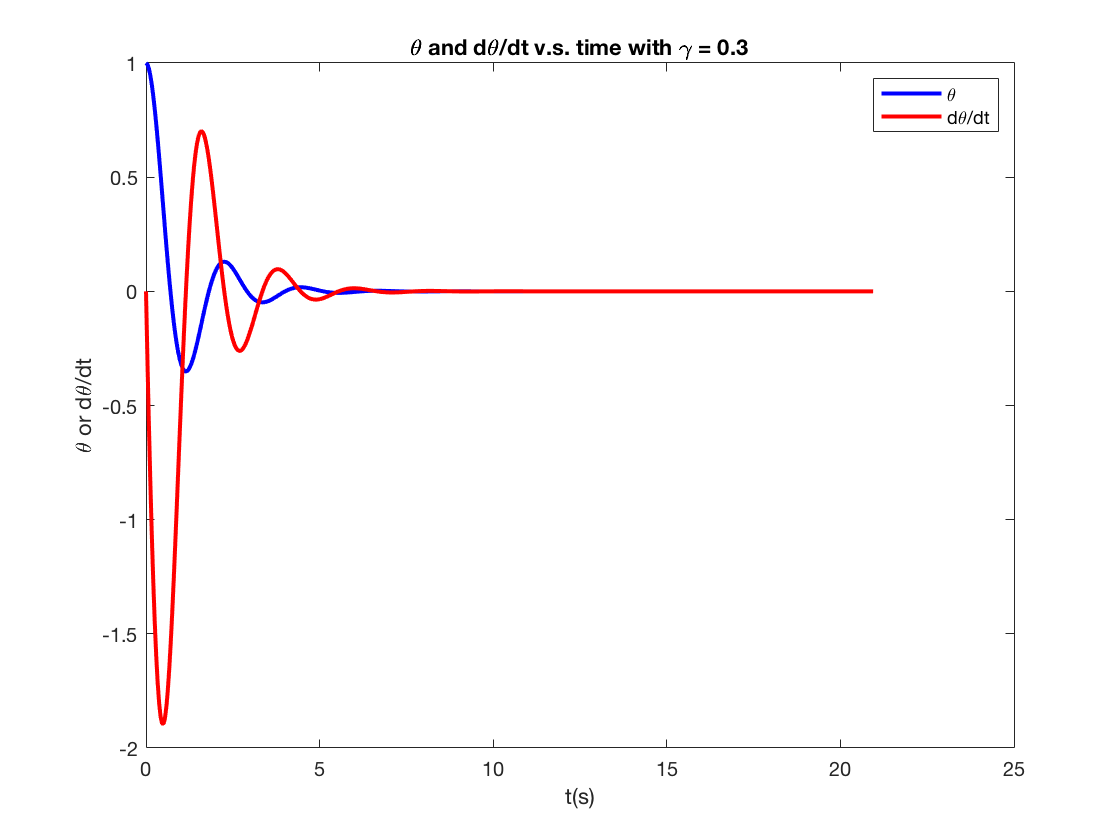

T = 2.2245

T ratio = 1.009, ang. freq. ratio is 0.9911


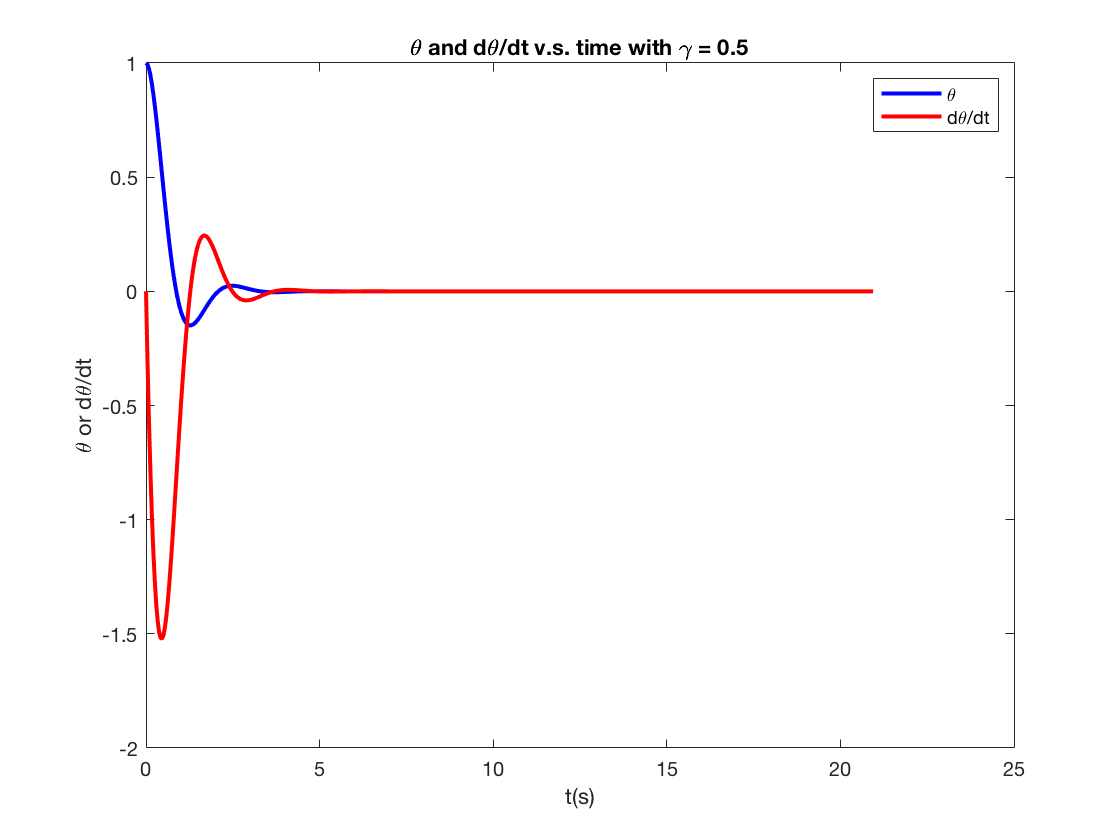

T = 2.4763

T ratio = 1.123, ang. freq. ratio is 0.8903


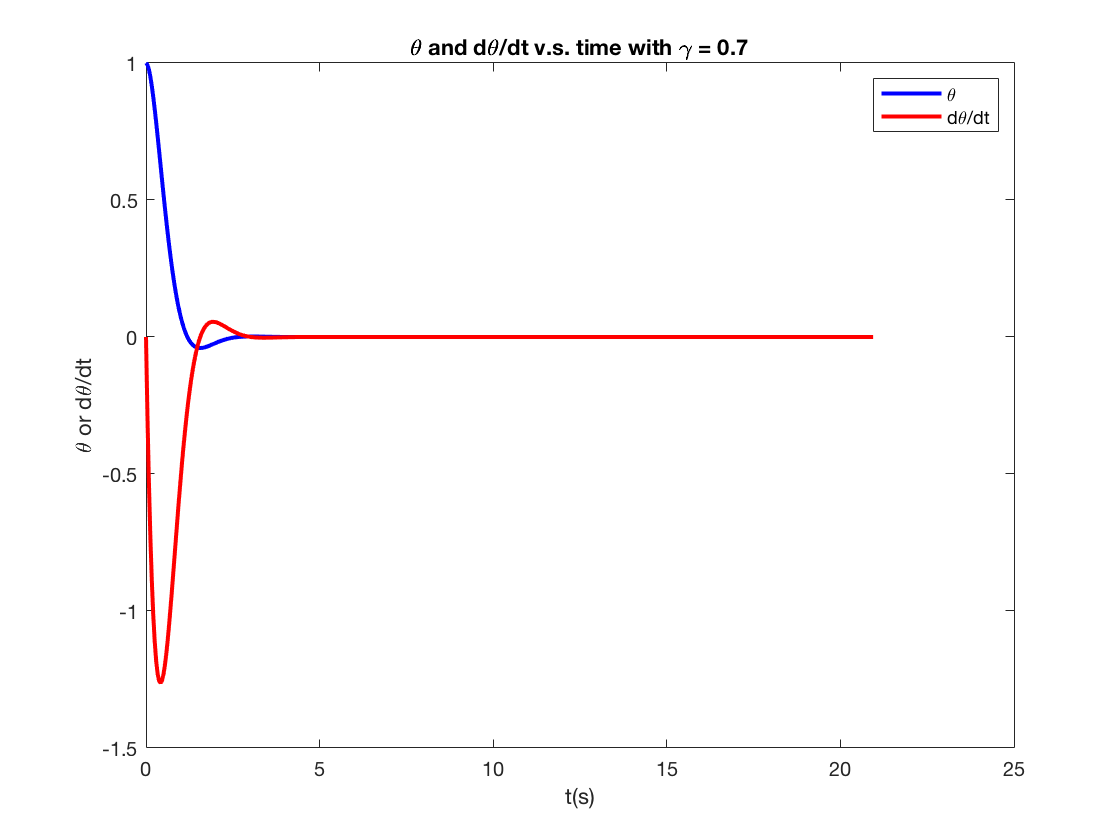

T = 3.1059

T ratio = 1.409, ang. freq. ratio is 0.7098


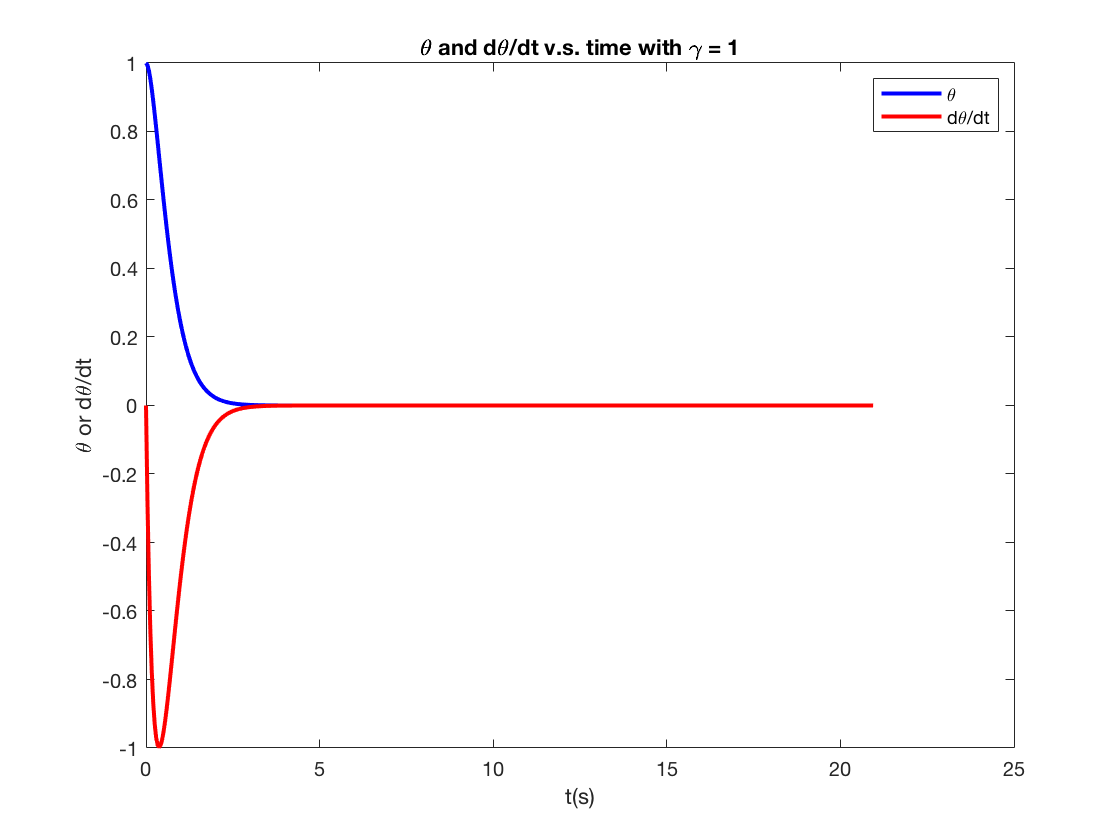

T = NaN

T ratio = NaN, ang. freq. ratio is NaN


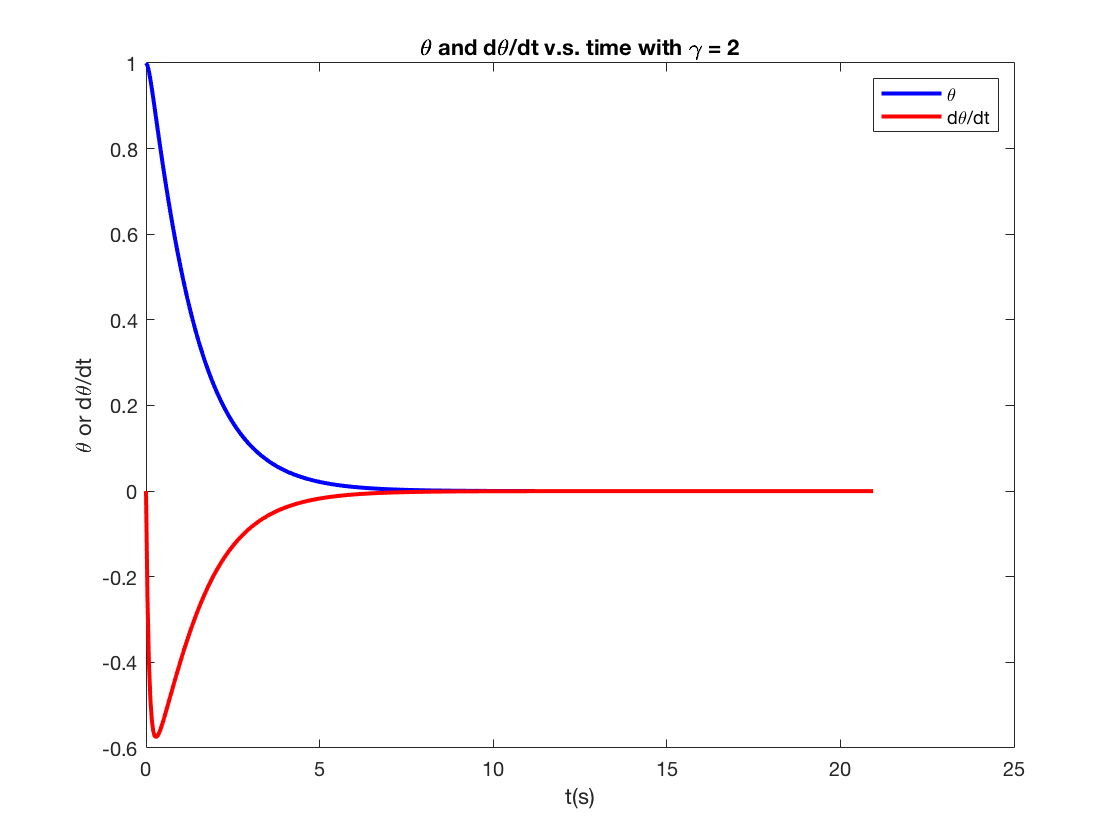

T = NaN

T ratio = NaN, ang. freq. ratio is NaN


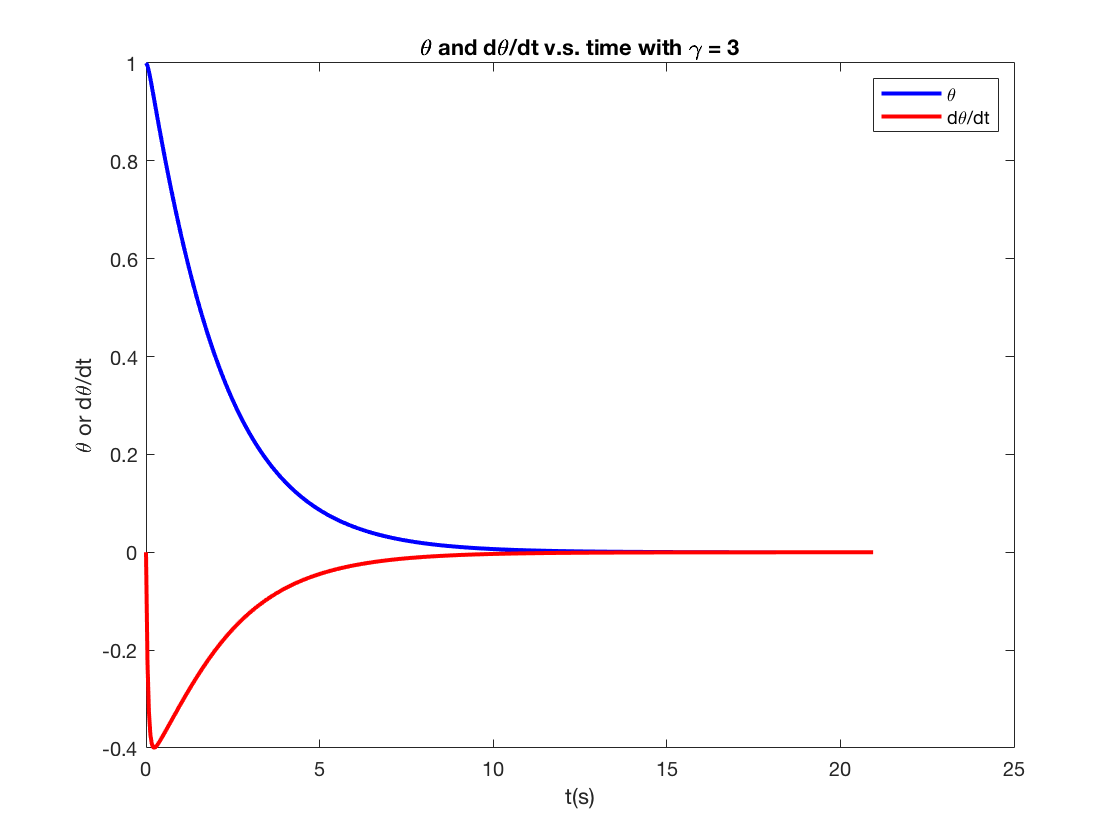

T = NaN

T ratio = NaN, ang. freq. ratio is NaN



gamma_list = [0.1,0.3,0.5,0.7,1,2,3];

for i=1:7
    [T, sol] = damped_oscillator(3,gamma_list(i),1,0);
    T
    omega = 2*pi/T;
    disp(['T ratio = ' num2str(T/T_undamped,4) ', ang. freq. ratio is ' num2str(omega...
    /omega_undamped,4)])
end

Here I set gamma = b / (2*m*omega0).

We expect the period to be larger with larger damping factor. But there is something wrong with gamma = 0.1.

My result shows, for gamma < 1, larger damping ratio makes period larger and angular frequency smaller. For gamma > =1, no oscillation observed. Larger gamma makes decay slower.